# Vehicle Data Class Reference

This is meant to be a reference on how you can use the unified Vehicle class to do cool VD stuff

Adapted from some sweeps I did last year, but done better, and the comments in vehicle.m.

Ben Model, 8/27/25

First things first, about it:

**Purpose**

The **Vehicle** object centralizes all design and simulation parameters of a car in one place. Instead of scattering constants across code or models, everything is stored in a single object that can be passed to MATLAB and Simulink simulations. Updating the spreadsheet updates the vehicle everywhere.

**Usage**

- **Create a vehicle: **create a  new one with:

- **Access Parameters like: **in your code, you can create new variables referenced like this, or simply use the zr.mass_total wherever you would put mass

- **Update parameters: **Certain parameters are used to calculate other parameters, for instance car + driver mass make 'mass_total'. You can easily set the car mass to something else whenever you want, and then recalculate all of the derived parameters. An example of this is below

- **Reset Parameters: **Parameters can easily be reset to the default from the spreadsheet

(those are screenshots lmao, haven't properly initialized yet)

## More in depth stuff + examples

Here's some (hopefully) running examples of how this can be used, with much more in depth explanations

### loading the parameters into the file:

%filepath = 'C:\Users\benmo\OneDrive - The University of Akron\Documents - Zips Racing FSAE\ZR25\Vehicle Dynamics\System\Analysis\'

**DONT DO STUFF LIKE THAT ^^**

Do stuff like this instead:

Use github. (non-negotiable, thats where this is stored) make your working directory:

'\filepath to your github folder\GitHub\Vehicle-Dynamics\MATLAB\';

This can be checked by running the command 'pwd' (print working directory). If I was nice I'd write a script to run that sets that for you. Teehee. (I added some filepath validation in the class, you'll at least be yelled at now if something is wrong)

pwd

ans = 'C:\Users\benmo\Documents\GitHub\Vehicle-Dynamics\MATLAB'

Then, filepaths can look as clean as this, and **MOST IMPORTANTLY will work on other peoples computers!!!!!**

filepath = '\vehicle_data\';
filename = 'zr25_data.xlsx';

fileJawn = [filepath,filename]

fileJawn = '\vehicle_data\zr25_data.xlsx'

### Creating the vehicle object:

zr = vehicle(fileJawn);

✅ Setup looks alright
meow 🗨️🐈
Vehicle object created successfully!


So the excel sheet you point to holds all the design parameters. I have termed these parameters "static" parameters. Think of them as minimum set or the basis you need to calculate all the other ones. The "derived" parameters are calculated from the static parameters when a new vehicle instance is created in your script, or you update or reset a vehicle.

**The excel sheet has to be closed to be read!** A bit annoying sometimes, but not that bad. You can easily set values in matlab, if you want to change something there is no need to do it in excel until you want it permanent. (jk it sorta just ran for me)

#### Static Parameters: **Instantiated with the vehicle, or set by user**

zr.vehicle_mass

ans = 250

zr.vehicle_mass = 200;

#### Calculated Parameters: On update

(the class constructor and the reset method simply call the update method internally)

Updating uses the current set of static parameters to calculate the derived parameters. 

**        Be careful! **If you've set a calculated parameter manually, calling update will reset it! Just be aware. Read through the class itself for lists of static vs calculated parameters

zr.mass_total   % (now stale, need to update)

ans = 322.7300

zr.update
zr.mass_total

ans = 272.7300

#### Reset

zr.reset
zr.vehicle_mass

ans = 250

zr.mass_total

ans = 322.7300

Resetting does not query the spreadsheet again, the original table read from the excel spread sheet is stored immutably as long as the object exists in the workspace. There is some overhead resetting, but it's not too terrible in practice, computers are pretty fast.

## Example: Creating simple Sweeps

This is meant to show how you can use the class to make pretty graphs - it is adapted from some code I wrote last year but simplified. Still a really useful tool on it's own though. 

**Problem Statement**: Create a chart that shows how TLLTD changes with +/-20% changes to spring rates, bar rates, and roll centers

%% Record the original values
frontSpringRate = zr.spring_rate_front;
rearSpringRate = zr.spring_rate_rear;

roll_center_front = zr.roll_center_front;
roll_center_rear = zr.roll_center_rear;

frontBarRate = zr.bar_spring_rate_front;
rearBarRate = zr.bar_spring_rate_rear;

### Trial setup

Start with target value, and run trials from -20% to +20% of target value, in 21 step increments

nTrials = 21;
trialPercent = 1-linspace(.2,-.2,nTrials)

trialPercent =     0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800    1.0000    1.0200    1.0400    1.0600    1.0800    1.1000    1.1200    1.1400    1.1600    1.1800    1.2000


Next is a simple for loop sweep through each trial value. After setting the new value, zr.update is called to update all derived parameters based on this new value. However, be careful! zr.update will calculate based on the so-called 'static parameters' (the ones listed in the spreadsheet). If you set one that isn't, and then update, it will be cleared!

%% Rear Sping Rate
for i = 1:1:nTrials
    % Set trial Value and update
    zr.spring_rate_rear = trialPercent(i)*rearSpringRate;
    zr.update;

    % record the newly calculated total lateral load distribution
    trialRSR(i) = zr.tlltd;

end
zr.reset;

Notice I call reset after each loop. This is so that the next trial starts again with the default values in the spreadsheet

%% Front Spring Rate
for i = 1:1:nTrials
    % Set trial Value and update
    zr.spring_rate_front = trialPercent(i)*frontSpringRate;
    zr.update;
 
    trialFSR(i) = zr.tlltd;

end
zr.reset;

This way works, but is not as compact as it can be. Lets just tackle a few more and plot them:

for i = 1:1:nTrials
    % Rear Roll Center
        zr.roll_center_rear = trialPercent(i)*roll_center_rear;
        zr.update; trialRRC(i) = zr.tlltd; zr.reset;
    % Front Roll Center
        zr.roll_center_front = trialPercent(i)*roll_center_front;
        zr.update; trialFrc(i) = zr.tlltd; zr.reset;
    % Rear Bar Rate
        zr.bar_spring_rate_rear = trialPercent(i)*rearBarRate;
        zr.update; trialRbr(i) = zr.tlltd; zr.reset;
    % Front Bar Rate
        zr.bar_spring_rate_front = trialPercent(i)*frontBarRate;
        zr.update; trialFbr(i) = zr.tlltd; zr.reset;
end

    (a bit more compactly, but the same, just resetting in between. modest but not a huge performance hit)

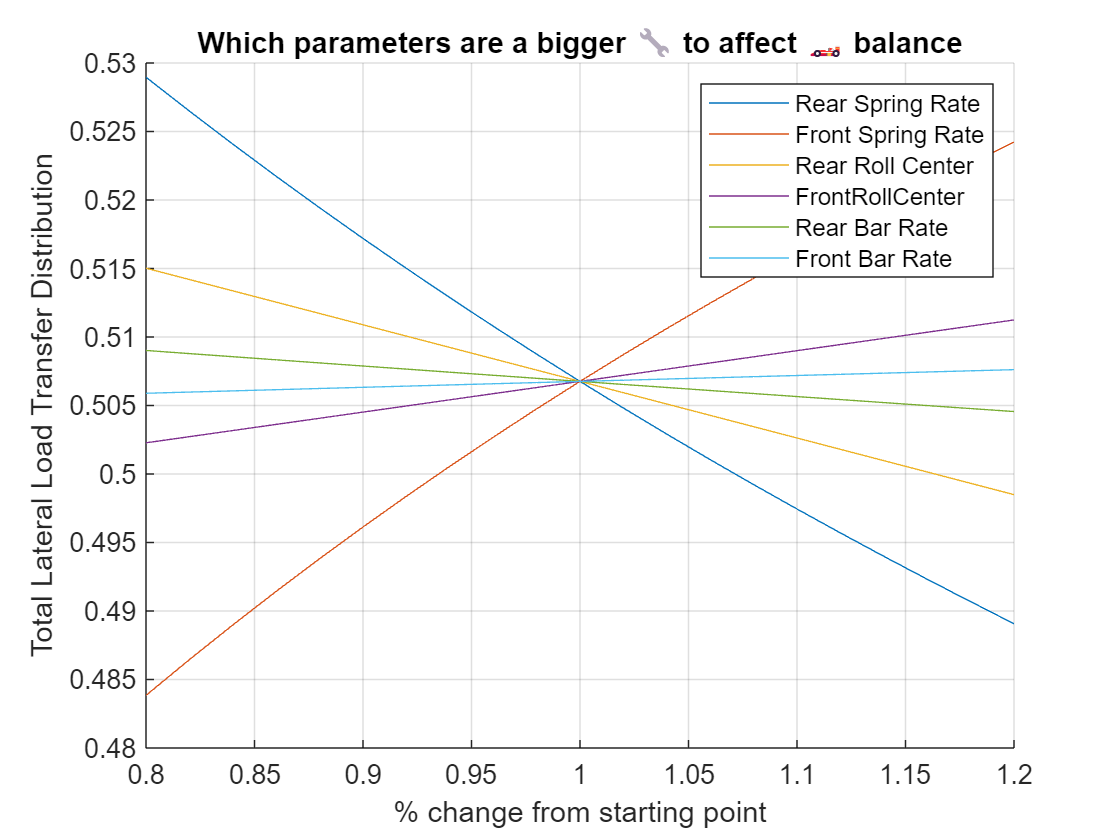

%% Plots
figure(1)
    hold on
    plot(trialPercent,trialRSR); plot(trialPercent,trialFSR)
    plot(trialPercent,trialRRC); plot(trialPercent,trialFrc)
    plot(trialPercent,trialRbr); plot(trialPercent,trialFbr)
    grid on
    
    legend('Rear Spring Rate','Front Spring Rate','Rear Roll Center','FrontRollCenter','Rear Bar Rate','Front Bar Rate')
    xlabel('% change from starting point')
    ylabel('Total Lateral Load Transfer Distribution')
    title('Which parameters are a bigger 🔧 to affect 🏎️ balance')
    hold off

Tadaaaaa. This is a really useful chart, and gives a sense of how sensitive the car will be to certain changes. This can easily be extended, for instance one could do sensitivity studies to show the effect of motion ratio error (do this!!!!), manufacturing tolerance errors (do this!! are our roll centers where we think? how does that change balance??)

Hopefully you all continue to use this tool and it proves useful. I also have written a functionally equivalent one in Julia. Don't mix up the files though! the intention is that ONE file drives the whole design for a car, eg zr25, zr26, etc, so in later years the team can easily compare with the same tools. Don't be afraid to add more parameters either! Just remember to keep the excel file and matlab file updated together.